clear; close all; clc;

%% -------------------- Step A: Define Problem Parameters --------------------
N = 10;                     % number of rows
RL = 20;                    % row length
W = 2.5;                    % implement width (row spacing)
L = 3;                      % tractor length
Ld = 1.5;                   % look-ahead distance
gamma_limit = deg2rad(60);  % steering limit
Rmin = L / tan(gamma_limit);  % minimum turning radius
reedsConnObj = reedsSheppConnection;
reedsConnObj.MinTurningRadius = 5;
% Start and end positions
x_start = -3 * W;
y_start = RL / 2;
x_end = x_start;
y_end = y_start;

% Coordinates of headland nodes (lower and upper)
x_lower = W + 2.5 * (0:N-1); % added 2.5 m to correct X coordinates
y_lower = zeros(1, N);

x_upper = x_lower;
y_upper = RL * ones(1, N);

% Assemble full node coordinate list (1=start, 2..N+1=lower, N+2..2N+1=upper, 2N+2=end)
x = [x_start, x_lower, x_upper, x_end];
y = [y_start, y_lower, y_upper, y_end];

% Plot for verification
figure; plot(x, y, 'ko'); text(x + 0.2, y + 0.2, string(1:2*N+2)); axis equal;
title('Node Layout Verification'); xlabel('X [m]'); ylabel('Y [m]');
status = mkdir('results');

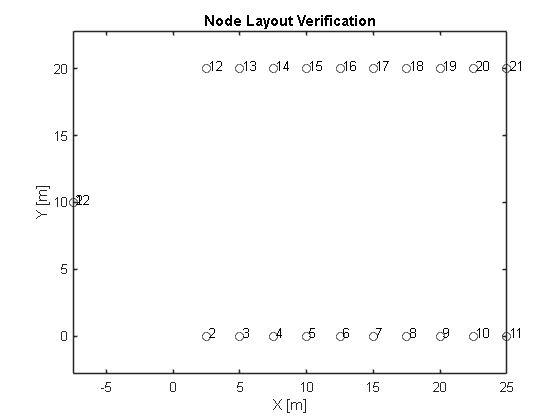

saveas(gcf, "results\node_layout.png")

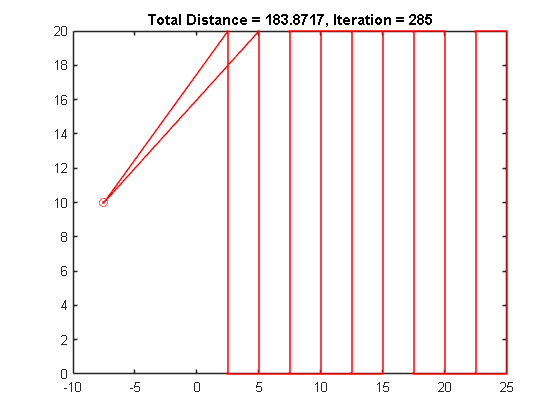

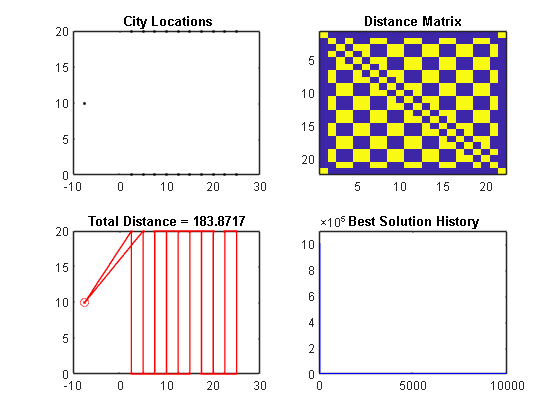


%% -------------------- Step B: Build Cost Matrix --------------------
HUGE = 1e6; % Large penalty value
DMAT = HUGE * ones(2*N+2); % Initialize with large values

% 1. Row traversal cost (zero cost between lower-upper of the same row)
for i = 2:N+1 % lower nodes
    for j = N+2:2*N+1 % upper nodes
        if (j - i) == N
            DMAT(i,j) = 0; % row traversal is "free"
            DMAT(j,i) = 0;
        end
    end
end

% 2. Headland turning costs via Reeds–Shepp fishtail turns
%    (requires a reedsSheppShortestPath + length extractor)
for i = 2:N                    % bottom nodes only
    for j = i+1:N+1            % look only to the right of i
        % ── 1. Pose definitions ───────────────────────────────────
        % bottom headland: driving south → north
        if all([i j] >= 2 & [i j] <= N+1)
            q0 = [ x(i),   y(i),  -pi/2 ];   % start pose (x,y,θ)
            q1 = [ x(j),   y(j),   pi/2 ];   % end   pose (x,y,θ)
        else
            % top headland: driving north → south
            q0 = [ x(i),   y(i),   pi/2 ];
            q1 = [ x(j),   y(j),  -pi/2 ];
        end

        % ── 2. Compute the shortest Reeds–Shepp path ───────────────
        % (must be on your path‐planning toolbox or implemented already)
        [pathSegs, cost] = connect(reedsConnObj, q0, q1);  % :contentReference[oaicite:0]{index=0}


        % ── 4. Fill the distance matrix symmetrically ─────────────
        DMAT(i,      j    ) = cost;
        DMAT(j,      i    ) = cost;
        DMAT(i+N,    j+N  ) = cost;
        DMAT(j+N,    i+N  ) = cost;
    end
end


% 3. Manhattan distances from start and end nodes to all field nodes
for i = 2:2*N+1
    DMAT(1,i) = abs(x(1) - x(i)) + abs(y(1) - y(i));
    DMAT(i,1) = DMAT(1,i); % symmetry

    DMAT(2*N+2,i) = abs(x(2*N+2) - x(i)) + abs(y(2*N+2) - y(i));
    DMAT(i,2*N+2) = DMAT(2*N+2,i); % symmetry
end

% 4. Prohibit direct start-to-end transitions
DMAT(1,2*N+2) = HUGE;
DMAT(2*N+2,1) = HUGE;

% % Add penalties for crossing the field diagonally (disable jumps not to neighbor rows)
% for i = 2:N+1  % lower nodes
%     for j = 2:N+1  % other lower nodes
%         if abs(i - j) > 1
%             DMAT(i, j) = HUGE;
%             DMAT(i + N, j + N) = HUGE;
%         end
%     end
% end


%% -------------------- Solve TSP (Step B Completion) --------------------
XY = [x', y'];
t = cputime;
resultStruct = tspof_ga('xy', XY, 'DMAT', DMAT, ...
                        'SHOWRESULT', true, ...
                        'SHOWWAITBAR', true, ...
                        'SHOWPROG', true);

E = cputime - t; % computation time

route = [1, resultStruct.optRoute, 2*N+2]; % full node sequence

% Output result
disp('Computed Optimal Route (Node Indices):');

Computed Optimal Route (Node Indices):


disp(route);

     1    13     3     6    16    18     8    11    21    20    10     9    19    15     5     7    17    14     4     2    12    22



disp(['Computed Minimum Distance: ', num2str(resultStruct.minDist)]);

Computed Minimum Distance: 183.8717


disp(['Computation Time: ', num2str(E), ' seconds']);

Computation Time: 3 seconds


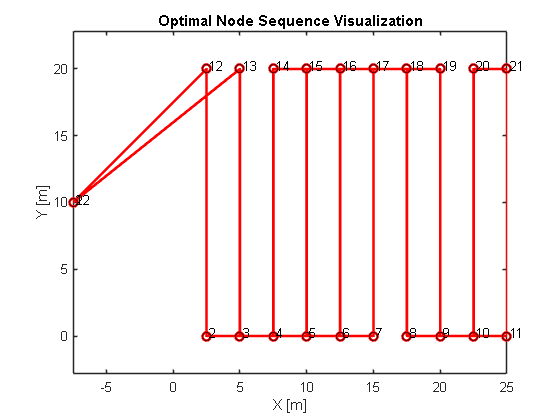


% Save output
% Open a new file (or overwrite if it exists)
fid = fopen('results\results.txt','w');

% Write each piece
fprintf(fid, 'Computed Optimal Route (Node Indices):\n');
fprintf(fid, '%d ', route);          % print each index with a space
fprintf(fid, '\n\n');                % blank line

fprintf(fid, 'Computed Minimum Distance: %.4f\n', resultStruct.minDist);
fprintf(fid, 'Computation Time: %.4f seconds\n', E);

% Close the file
fclose(fid);

%% Plot Solution
figure; plot(x(route), y(route), 'r-o', 'LineWidth', 2);
hold on; plot(x, y, 'ko'); text(x + 0.2, y + 0.2, string(1:2*N+2));
title('Optimal Node Sequence Visualization');
xlabel('X [m]'); ylabel('Y [m]'); axis equal;

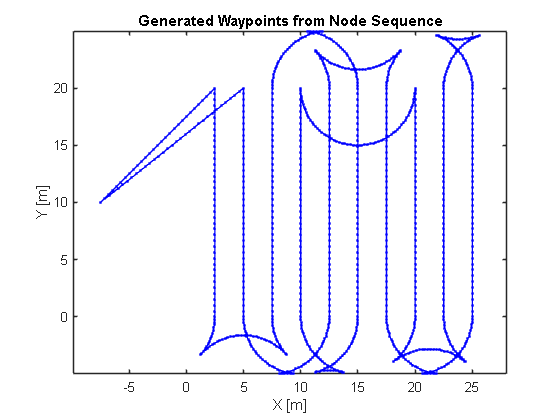


%% -------------------- Step C: Generate Waypoints Along the Node Sequence --------------------
% ── Step C -- build dense way-points (with Π/Ω turns) ────────────────
waypoints = [];

for k = 1:numel(route)-1
    i  = route(k);
    j  = route(k+1);
    p1 = [x(i), y(i)];
    p2 = [x(j), y(j)];

    % ----- straight row traversal (paired lower<->upper of the same row)
    paired = ( (i>=2 && i<=N+1 && j-i==N) || ...
               (j>=2 && j<=N+1 && i-j==N) );
    if paired
        nPts = ceil(norm(p2-p1)/0.5);
        xs   = linspace(p1(1),p2(1),nPts)';
        ys   = linspace(p1(2),p2(2),nPts)';
        waypoints = [waypoints; xs(2:end) ys(2:end)];
        continue
    end

    % ----- Π / Ω turn  (both nodes on the same headland)
    sameBottom = all([i j] >= 2      & [i j] <= N+1);
    sameTop    = all([i j] >= N+2    & [i j] <= 2*N+1);
    if sameBottom || sameTop
        % define start/end orientations
        if sameBottom          % driving south -> north
            theta0 = -pi/2;
            theta1 =  pi/2;
        else                   % top headland: north -> south
            theta0 =  pi/2;
            theta1 = -pi/2;
        end
        q0 = [ x(i), y(i), theta0 ];
        q1 = [ x(j), y(j), theta1 ];

        % connect the two poses, returning the shortest segment
        [pathSegs, ~] = connect(reedsConnObj, q0, q1);  % :contentReference[oaicite:0]{index=0}
        seg = pathSegs{1};

        % sample every 0.25 m along the segment
        L = seg.Length;
        s = 0:0.25:L;                                  % :contentReference[oaicite:1]{index=1}
        poses = interpolate(seg, s);

        % append only the x,y (drop the duplicate q0)
        waypoints = [waypoints; poses(2:end,1:2)];

        continue
    end

    % ----- start/end approaches → straight line
    nPts = ceil(norm(p2-p1)/0.5);
    xs   = linspace(p1(1),p2(1),nPts)';
    ys   = linspace(p1(2),p2(2),nPts)';
    waypoints = [waypoints; xs(2:end) ys(2:end)];
end

% Plot the generated waypoints
figure; plot(waypoints(:,1), waypoints(:,2), 'b.-'); axis equal;
title('Generated Waypoints from Node Sequence');
xlabel('X [m]'); ylabel('Y [m]');
saveas(gcf, "results\waypoints.png")

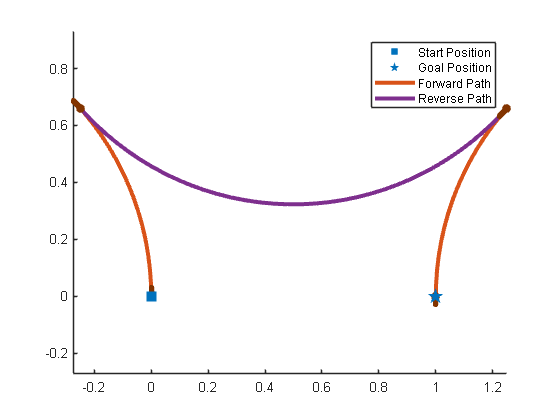

startPose = [0 0 pi/2]; goalPose= [ 1 0 -pi/2];
reedsConnObj = reedsSheppConnection;
[pathSegObj,pathCosts] = connect(reedsConnObj,startPose,goalPose);
show(pathSegObj{1}); axis equal;